## Plot data and external control signal

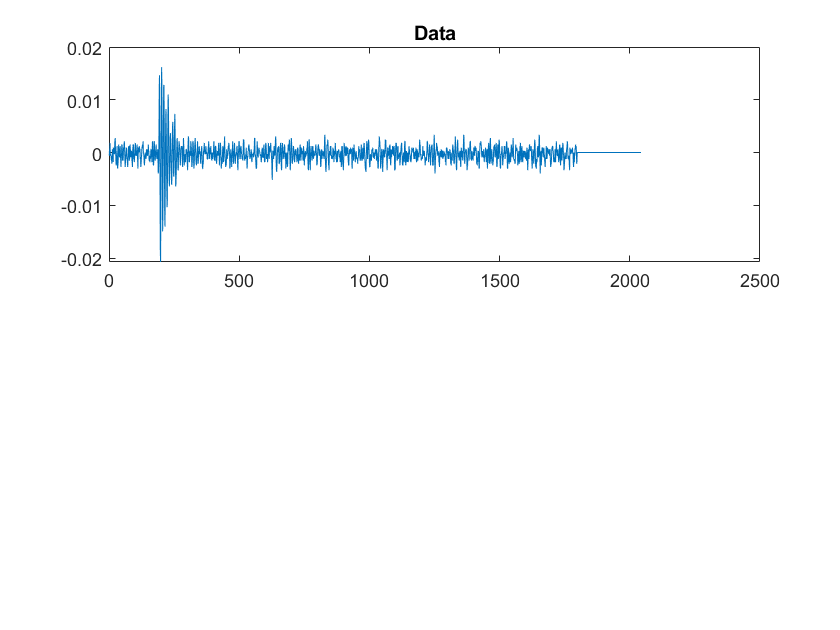

% Get example data
foldername = string(pwd()) + "\..\dat\";
% filename = foldername + "ex1_linear_system.mat"
filename = foldername + "ex1_linear_system_from_Purdue.csv";
% data_struct = importdata(filename);

data_table = readtable(filename);
X = data_table{:,2}';
aug = 5;
X = time_delay_embed(X, aug);
% X = data_struct.data;
% U = data_struct.control_signal;

% Plot
figure;

subplot(2,1,1)
plot(X(1,:))
title("Data")


% subplot(2,1,2)
% plot(U)
% title("Control signal")

## Do DMDc using the known control signal

% Exact DMDc; uses L2 solution
% [A, B, dat_reconstruction] = simple_dmdc(X, U);
% 
% % Plot Reconstruction along with data
% figure;
% plot(X(1,:))
% plot(dat_reconstruction(1,:))
% legend("Data", "Reconstruction")
% title("DMDc Model; known control signal")

## Learn the control signal

% Returns a list of control signals with increasing sparsity
settings = struct('r_ctr',1, ... % Number of control signals
                  'verbose',true, ... 
                   'num_iter',100); % Number of iterations
[all_U, all_A, all_B] =...
    learn_control_signals(X, settings);

Iteration 1/100
Number of nonzero control signals: 741
Iteration 2/100
Number of nonzero control signals: 704
Iteration 3/100
Number of nonzero control signals: 669
Iteration 4/100
Number of nonzero control signals: 636
Iteration 5/100
Number of nonzero control signals: 604
Iteration 6/100
Number of nonzero control signals: 574
Iteration 7/100
Number of nonzero control signals: 545
Iteration 8/100
Number of nonzero control signals: 518
Iteration 9/100
Number of nonzero control signals: 492
Iteration 10/100
Number of nonzero control signals: 467
Iteration 11/100
Number of nonzero control signals: 444
Iteration 12/100
Number of nonzero control signals: 422
Iteration 13/100
Number of nonzero control signals: 401
Iteration 14/100
Number of nonzero control signals: 381
Iteration 15/100
Number of nonzero control signals: 362
Iteration 16/100
Number of nonzero control signals: 344
Iteration 17/100
Number of nonzero control signals: 327
Iteration 18/100
Number of nonzero control signals: 311
I

Number of nonzero control signals: 0


Elapsed time is 0.372507 seconds.


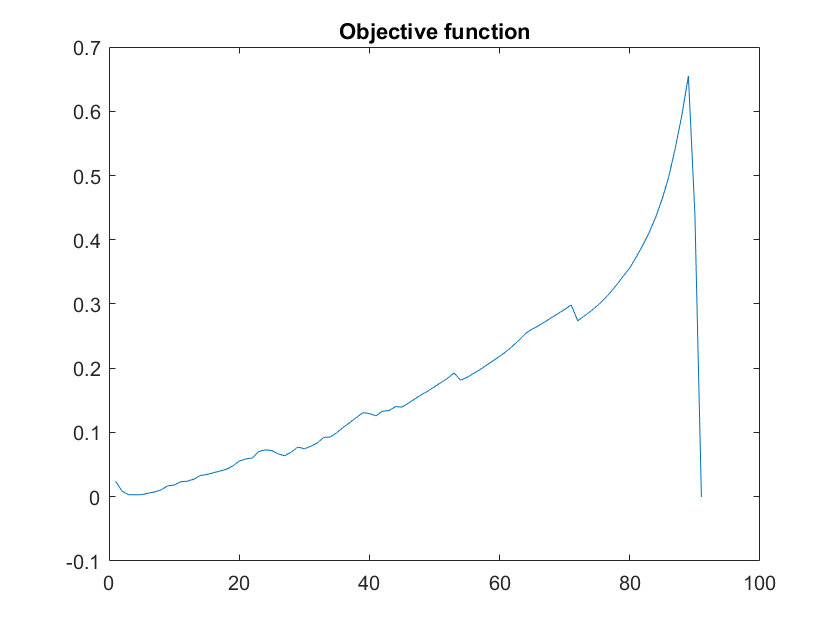


% Calculate some simple statistics about the control signal
all_nnz = zeros(size(all_U));
all_objective = all_nnz;
for i = 1:length(all_U)
    all_nnz(i) = nnz(all_U{i});
    all_objective(i) = acf(all_U{i}', 1, false);
end
all_objective(end) = all_objective(end-1);

% Get "best" signals and plot them
figure;
plot(all_objective)
title('Objective function')

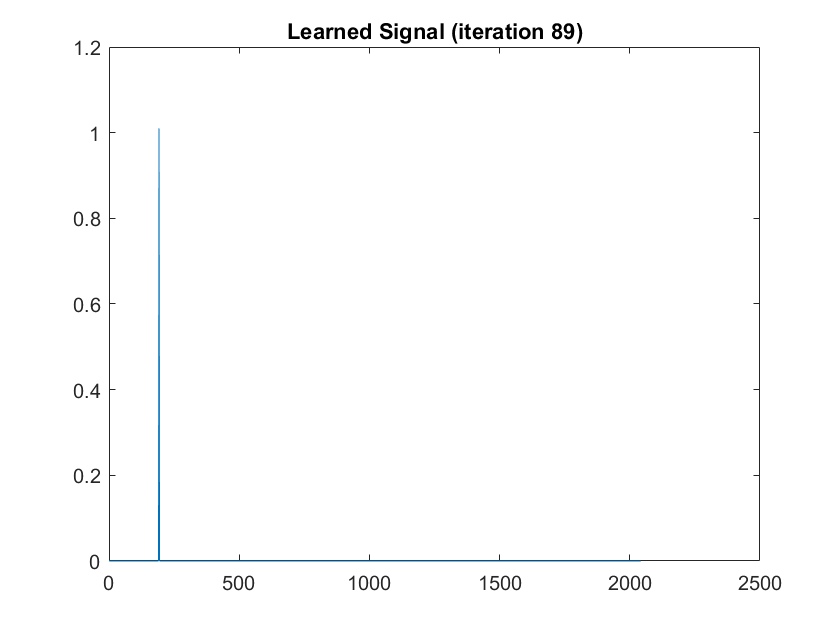


[~, ind_best] = max(all_objective);
best_U = all_U{ind_best};

figure;
plot(best_U);
title(sprintf('Learned Signal (iteration %d)', ind_best))

## Plot Reconstruction using learned control signal

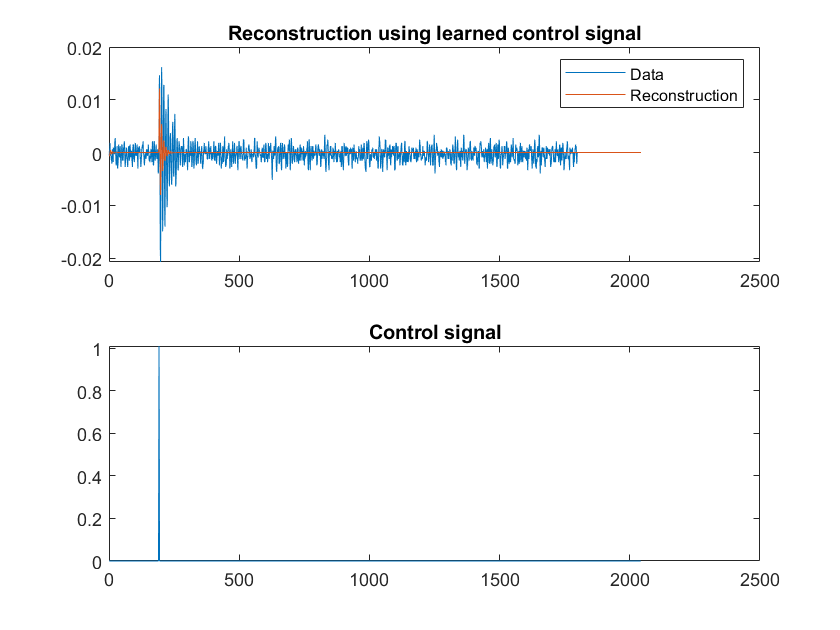

% Get learned matrices
best_A = all_A{ind_best};
best_B = all_B{ind_best};

% Initial condition
x0 = X(:,1);

% Calculate reconstruction
learned_X = calc_reconstruction_dmd(x0, [], best_A, best_B, best_U);

% Plot
figure;

subplot(2,1,1)
plot(X(1,:))
hold on
plot(learned_X(1,:))
legend("Data", "Reconstruction")
title("Reconstruction using learned control signal")

subplot(2,1,2)
plot(best_U)
title("Control signal")